L = 1;
N = 11;
delta_x = L/N;
delta_p = 2*pi/L;

% vx vp are bases:

The sampling basis of $|x>$ is presented as vx, in the period L. 

The sampling basis of $|p>$ is presented as vp, in periond of $2\frac{\pi }{L}N$

vx = linspace(0,L,N+1);
vx = vx(1:end-1);
vp = linspace(-2*pi/L*(N-1)/2,2*pi/L*(N-1)/2,N);


The value of $|x>$ and $|p>$ is presented as matrix mx and mp

who's column is the right vector. and the row of their conjugate

present the left vector.  

mx = eye(N);
[m1,m2] = meshgrid(vp,vx);
mp = exp(1j*m1.*m2);
mx = mx./sqrt(delta_x);
mp = mp./sqrt(delta_p)/sqrt(N);
mxd = mx';
mpd = mp';


The presentation of the operator  and  in the base of 


op_P = zeros(N,N);
op_X = zeros(N,N);
for i=1:N
    
   op_P = delta_p*vp(i)*mp(:,i)*mpd(i,:)+op_P;
   op_X = delta_x*vx(i)*mx(:,i)*mxd(i,:)+op_X;
    
end


The testing code:


nx = 2;
np = 5;

tvx = mx(:,nx);
tvp = mp(:,np);

tm1 = op_P*tvx;
tm2 = zeros(N,N);
for i=1:N
   tm2 = tm2 + delta_p*vp(i)*exp(-1j*vp(i)*vx(nx))/sqrt(2*pi)*mp(:,i); 
end
disp(max(max(abs(tm1-tm2))));

   7.1054e-15




tm1 = tvp;
tm2 = zeros(N,N);
for i=1:N
   tm2 = tm2 + delta_x*exp(1j*vx(i)*vp(np))/sqrt(2*pi)*mx(:,i); 
end
disp(max(max(abs(tm1-tm2))));

   1.5516e-17




nx = 7;
tm1 = op_P*mx(:,nx);
tm2 = zeros(N,N);
for ix=1:N
    for ip=1:N
        
        tm2 = tm2 + delta_x*delta_p...
            *1/2/pi*exp(1j*(vx(ix)-vx(nx))*vp(ip))*vp(ip)*mx(:,ix);
        
    end
end
disp(max(max(abs(tm1-tm2))));

   4.0856e-14



The analysis of the formula $\int dp \frac{p}{2\pi} \exp{(ixp)}$

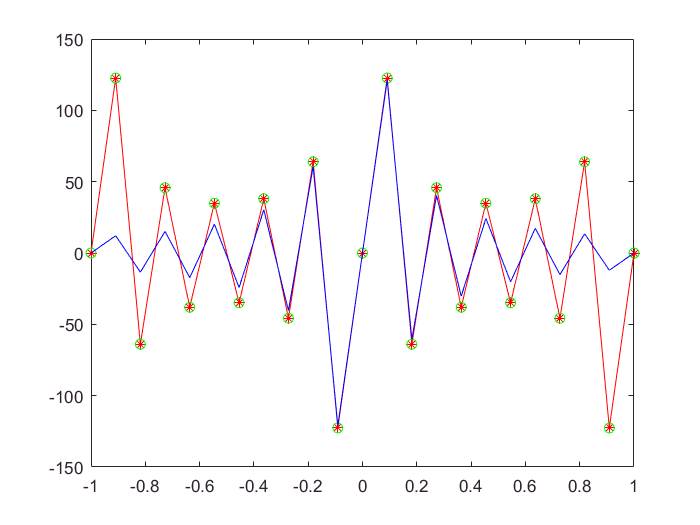


vx2 = linspace(-L,L,2*N+1);

[mp2,mx2] = meshgrid(vp,vx2);
tm = mp2/2/pi.*exp(1j*mx2.*mp2)*delta_p;
vdisx = sum(tm,2);

close(figure(1));figure(1);
plot(vx2,imag(vdisx),'-r*');

close(figure(2));figure(2);
plot(vx2,real(vdisx),'-b*');

vnx = -N:N;
fx = -2*pi/L*N.*exp(1j*2*pi/N*vnx*(N+1)/2)./(1-exp(1j*2*pi/N*vnx));
fx(1) = 0;
fx(N+1) = 0;
fx(2*N+1) = 0;

fx_app = 1/1j*N^2/L*power(-1,vnx)./vnx;
fx_app(1) = 0;
fx_app(N+1) = 0;
fx_app(2*N+1) = 0;

figure(1);
hold on;
plot(vx2,imag(fx),'go');
plot(vx2,imag(fx_app),'b');

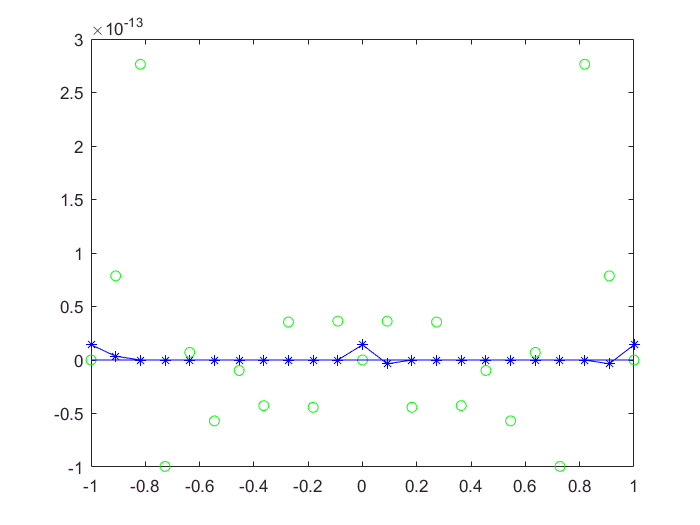

figure(2);
hold on;
plot(vx2,real(fx),'go');
plot(vx2,real(fx_app),'b');

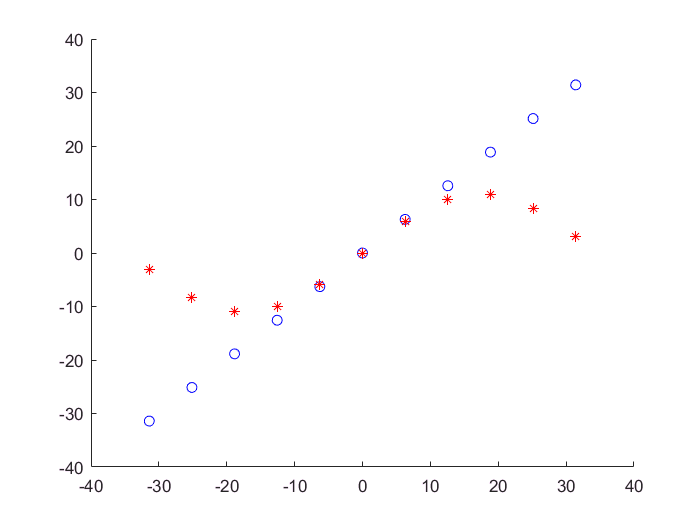


close(figure(3));
figure(3);hold on;
plot(vp,vp,'bo');
vgp = (exp(1j*delta_x*vp)-1)/1j/delta_x;
plot(vp,real(vgp),'r*');


op_Papp = zeros(N,N);
for i=1:N
    
   op_Papp = delta_p*vgp(i)*mp(:,i)*mpd(i,:)+op_Papp;
    
end

close(figure(4));
figure(4);hold on;
plot(vp,vp,'bo');
vgp2 = (exp(1j*delta_x*vp)-exp(-1j*delta_x*vp))/1j/2/delta_x;
plot(vp,real(vgp2),'r*');


op_Papp2 = zeros(N,N);
for i=1:N
    
   op_Papp2 = delta_p*vgp2(i)*mp(:,i)*mpd(i,:)+op_Papp2;
    
end


H = op_Papp*op_Papp/2;
delta_t = 0.01;

tm = exp(-1j*delta_t*H);
disp(tm)

  1 至 5 列

   0.8225 + 0.5688i   0.3530 - 0.9356i   0.8225 + 0.5688i   1.0000 + 0.0000i   1.0000 - 0.0000i
   1.0000 - 0.0000i   0.8225 + 0.5688i   0.3530 - 0.9356i   0.8225 + 0.5688i   1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   0.8225 + 0.5688i   0.3530 - 0.9356i   0.8225 + 0.5688i
   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   0.8225 + 0.5688i   0.3530 - 0.9356i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 - 0.0000i   0.8225 + 0.5688i
   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i
   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i
   1.0000 - 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i
   0.8225 + 0.5688i   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   0.3530 - 0.9356i   0.8225 